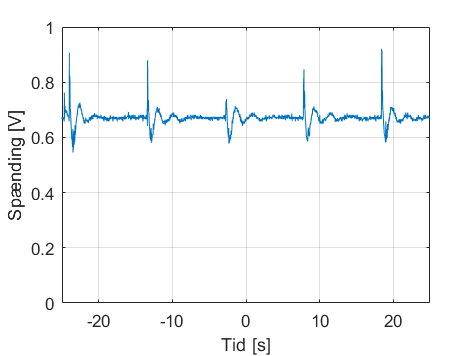

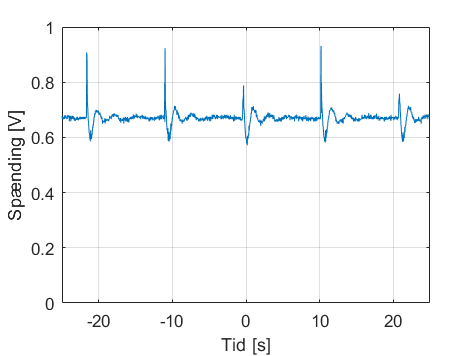

files = dir('*.csv');
for k = 1:length(files)
    MeasData = readmatrix(files(k).name, NumHeaderLines=2);
    Meas = MeasData(:,2);
    time = MeasData(:,1);
    figure(k+12);
    plotMeas(time, Meas)
    saveas(gcf,string(k),'epsc');
end

## Funktioner

function plotMeas(t, meas)
    plot(t, meas)
    xlabel('Tid [s]')
    ylabel('Spænding [V]')
    grid on
    xlim([-25 25])
    ylim([0 1])
end